## distance vs cross correlation calculation

fNames{1} ='Norm1HighBase_reg_segmented.mat'; 
fNames{2} ='Norm2HighBase_reg_segmented.mat'; 
fNames{3} ='Norm3HighBase_reg_segmented.mat'; 
fNames{4} ='Norm4HighBase_reg_segmented.mat'; 
fNames{5} ='Norm5HighBase_reg_segmented.mat'; 
fNames{6} ='Norm6HighBase_reg_segmented.mat'; 
fNames{7} ='Norm7HighBase_reg_segmented.mat'; 
fNames{8} ='Norm9HighBase_reg_segmented.mat'; 
fNames{9} ='Norm10HighBase_reg_segmented.mat';

cfsAll = [];
distAll = [];

for f = 1:length(fNames)
    f
    load(fNames{f})
    tsPass = normalize(double(cell2mat({result.segmves.tsPass}.'))');
    numVes = size(tsPass,2);
    pairs = nchoosek(1:numVes,2);
    numPairs = size(pairs,1);
    cfsMax = size(numPairs,1);
    distances = zeros(numPairs,1);

    for i = 1:numPairs 
        % compute vessel distance 
        coord1 = result.segmves(pairs(i,1)).rprops.Centroid;
        coord2 = result.segmves(pairs(i,2)).rprops.Centroid;
        x = [coord1;coord2];
        distances(i) = pdist(x,'euclidean');
    
        % compute max cross correlation 
        ts1 = tsPass(:,pairs(i,1));
        ts2 = tsPass(:,pairs(i,2));
        [xcf,~] = xcorr(ts1,ts2,0,'normalized');
        [M,I] = max(xcf);
        cfsMax(i) = M;
    end 
    cfsAll = [cfsAll;cfsMax'];
    distAll = [distAll;distances];
end 

f = 1

f = 2

f = 3

f = 4

f = 5

f = 6

f = 7

f = 8

f = 9

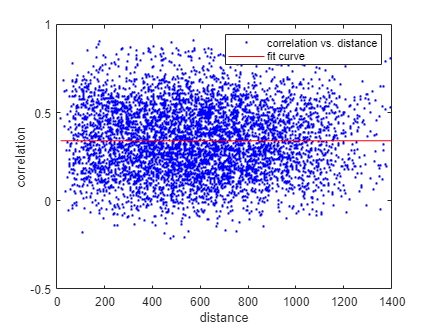


% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( distAll, cfsAll );

% Set up fittype and options.
ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'LinearLeastSquares');

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
f1 = figure( 'Name', 'linear regression' );
h = plot( fitresult, xData, yData );
legend( h, 'correlation vs. distance', 'fit curve', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'distance', 'Interpreter', 'none' );
ylabel( 'correlation', 'Interpreter', 'none' );
xlim([0 1400]);
ylim([-0.5 1])

fitresult 

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =  -7.082e-07  (-1.856e-05, 1.714e-05)
       p2 =      0.3407  (0.3289, 0.3524)

gof 

gof = struct with fields:
           sse: 229.3687
       rsquare: 1.0576e-06
           dfe: 5723
    adjrsquare: -1.7368e-04
          rmse: 0.2002


fNames{1} = 'Norm1HighPost_reg_segmented.mat'; 
fNames{2} ='Norm2HighPost_reg_segmented.mat'; 
fNames{3} ='Norm3HighPost_reg_segmented.mat'; 
fNames{4} ='Norm4HighPost_reg_segmented.mat'; 
fNames{5} ='Norm5HighPost_reg_segmented.mat'; 
fNames{6} ='Norm6HighPost_reg_segmented.mat'; 
fNames{7} ='Norm7HighPost_reg_segmented.mat'; 
fNames{8} ='Norm9HighPost_reg_segmented.mat'; 
fNames{9} ='Norm10HighPost_reg_segmented.mat';

cfsAll = [];
distAll = [];

for f = 1:length(fNames)
    f
    load(fNames{f})
    tsPass = normalize(double(cell2mat({result.segmves.tsPass}.'))');
    numVes = size(tsPass,2);
    pairs = nchoosek(1:numVes,2);
    numPairs = size(pairs,1);
    cfsMax = size(numPairs,1);
    distances = zeros(numPairs,1);

    for i = 1:numPairs 
        % compute vessel distance 
        coord1 = result.segmves(pairs(i,1)).rprops.Centroid;
        coord2 = result.segmves(pairs(i,2)).rprops.Centroid;
        x = [coord1;coord2];
        distances(i) = pdist(x,'euclidean');
    
        % compute max cross correlation 
        ts1 = tsPass(:,pairs(i,1));
        ts2 = tsPass(:,pairs(i,2));
        [xcf,~] = xcorr(ts1,ts2,0,'normalized');
        [M,I] = max(xcf);
        cfsMax(i) = M;
    end 
    cfsAll = [cfsAll;cfsMax'];
    distAll = [distAll;distances];
end 

f = 1

f = 2

f = 3

f = 4

f = 5

f = 6

f = 7

f = 8

f = 9

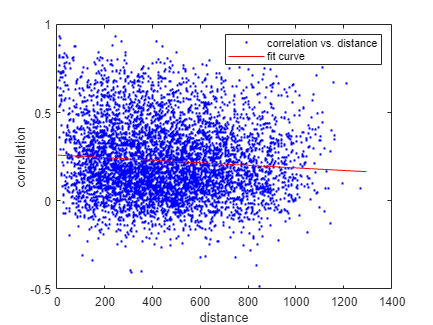


% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( distAll, cfsAll );

% Set up fittype and options.
ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'LinearLeastSquares');

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
f2 = figure( 'Name', 'linear regression' );
h = plot( fitresult, xData, yData );
legend( h, 'correlation vs. distance', 'fit curve', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'distance', 'Interpreter', 'none' );
ylabel( 'correlation', 'Interpreter', 'none' );
xlim([0 1400]);
ylim([-0.5 1])

fitresult 

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =  -7.291e-05  (-9.549e-05, -5.033e-05)
       p2 =      0.2591  (0.2474, 0.2708)

gof 

gof = struct with fields:
           sse: 251.5443
       rsquare: 0.0070
           dfe: 5723
    adjrsquare: 0.0068
          rmse: 0.2097


fNames{1} ='SHR1HighBase_reg_segmented.mat'; 
fNames{2} ='SHR2HighBase_reg_segmented.mat'; 
fNames{3} ='SHR3HighBase_reg_segmented.mat'; 
fNames{4} ='SHR4HighBase_reg_segmented.mat'; 
fNames{5} ='SHR5HighBase_reg_segmented.mat'; 
fNames{6} ='SHR6HighBase_reg_segmented.mat'; 
fNames{7} ='SHR7HighBase_reg_segmented.mat'; 
fNames{8} ='SHR8HighBase_reg_segmented.mat'; 
fNames{9} ='SHR9HighBase_reg_segmented.mat';

cfsAll = [];
distAll = [];

for f = 1:length(fNames)
    f
    load(fNames{f})
    tsPass = normalize(double(cell2mat({result.segmves.tsPass}.'))');
    numVes = size(tsPass,2);
    pairs = nchoosek(1:numVes,2);
    numPairs = size(pairs,1);
    cfsMax = size(numPairs,1);
    distances = zeros(numPairs,1);

    for i = 1:numPairs 
        % compute vessel distance 
        coord1 = result.segmves(pairs(i,1)).rprops.Centroid;
        coord2 = result.segmves(pairs(i,2)).rprops.Centroid;
        x = [coord1;coord2];
        distances(i) = pdist(x,'euclidean');
    
        % compute max cross correlation 
        ts1 = tsPass(:,pairs(i,1));
        ts2 = tsPass(:,pairs(i,2));
        [xcf,~] = xcorr(ts1,ts2,0,'normalized');
        [M,I] = max(xcf);
        cfsMax(i) = M;
    end 
    cfsAll = [cfsAll;cfsMax'];
    distAll = [distAll;distances];
end 

f = 1

f = 2

f = 3

f = 4

f = 5

f = 6

f = 7

f = 8

f = 9

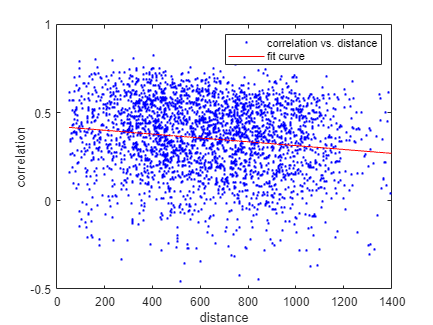


% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( distAll, cfsAll );

% Set up fittype and options.
ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'LinearLeastSquares');

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
f3= figure( 'Name', 'linear regression' );
h = plot( fitresult, xData, yData );
legend( h, 'correlation vs. distance', 'fit curve', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'distance', 'Interpreter', 'none' );
ylabel( 'correlation', 'Interpreter', 'none' );
xlim([0 1400]);
ylim([-0.5 1])

fitresult 

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =  -0.0001089  (-0.0001353, -8.254e-05)
       p2 =      0.4213  (0.4029, 0.4398)

gof 

gof = struct with fields:
           sse: 132.2258
       rsquare: 0.0217
           dfe: 2945
    adjrsquare: 0.0214
          rmse: 0.2119


fNames{1} = 'SHR1HighPost_reg_segmented.mat'; 
fNames{2} ='SHR2HighPost_reg_segmented.mat'; 
fNames{3} ='SHR3HighPost_reg_segmented.mat'; 
fNames{4} ='SHR4HighPost_reg_segmented.mat'; 
fNames{5} ='SHR5HighPost_reg_segmented.mat'; 
fNames{6} ='SHR6HighPost_reg_segmented.mat'; 
fNames{7} ='SHR7HighPost_reg_segmented.mat'; 
fNames{8} ='SHR8HighPost_reg_segmented.mat'; 
fNames{9} ='SHR9HighPost_reg_segmented.mat';

cfsAll = [];
distAll = [];

for f = 1:length(fNames)
    f
    load(fNames{f})
    tsPass = normalize(double(cell2mat({result.segmves.tsPass}.'))');
    numVes = size(tsPass,2);
    pairs = nchoosek(1:numVes,2);
    numPairs = size(pairs,1);
    cfsMax = size(numPairs,1);
    distances = zeros(numPairs,1);

    for i = 1:numPairs 
        % compute vessel distance 
        coord1 = result.segmves(pairs(i,1)).rprops.Centroid;
        coord2 = result.segmves(pairs(i,2)).rprops.Centroid;
        x = [coord1;coord2];
        distances(i) = pdist(x,'euclidean');
    
        % compute max cross correlation 
        ts1 = tsPass(:,pairs(i,1));
        ts2 = tsPass(:,pairs(i,2));
        [xcf,~] = xcorr(ts1,ts2,0,'normalized');
        [M,I] = max(xcf);
        cfsMax(i) = M;
    end 
    cfsAll = [cfsAll;cfsMax'];
    distAll = [distAll;distances];
end 

f = 1

f = 2

f = 3

f = 4

f = 5

f = 6

f = 7

f = 8

f = 9

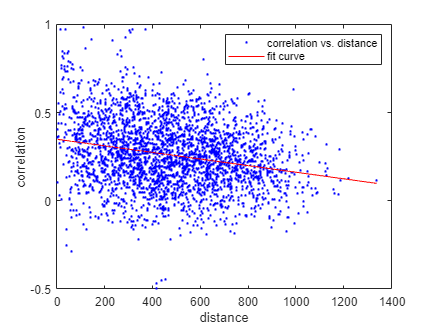


% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( distAll, cfsAll );

% Set up fittype and options.
ft = fittype( 'poly1' );
opts = fitoptions( 'Method', 'LinearLeastSquares');

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
f4 = figure( 'Name', 'linear regression' );
h = plot( fitresult, xData, yData );
legend( h, 'correlation vs. distance', 'fit curve', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'distance', 'Interpreter', 'none' );
ylabel( 'correlation', 'Interpreter', 'none' );
xlim([0 1400]);
ylim([-0.5 1])

fitresult 

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =   -0.000187  (-0.0002156, -0.0001585)
       p2 =      0.3488  (0.3336, 0.3639)

gof 

gof = struct with fields:
           sse: 108.3483
       rsquare: 0.0531
           dfe: 2945
    adjrsquare: 0.0528
          rmse: 0.1918
